# EE 451 Final Notes!

# Lisa Jacklin

## Walk Throughs/Notes

### Notes on Following Two Problems

% x_a is bandlimited to 1000 Hz. Minimum sampling frequency is 2000 Hz
% double that is 4000 Hz
%
% Fs = 4000
% Fs/2 = 2000 is mapped to pi
%
% 1 kHz is mapped to pi/2
% 500 Hz is mapped to pi/4
% 250 Hz is mapped to pi/8

% Decimation by 4 will "expand" the occupied bandwidth by the signal
% pi/2 will become 2*pi
% pi/4 will become pi
% pi/8 will become pi/2
%
% If we want to keep only the frequencies of interest, we must
% use a bandpass filter, between pi/8 (0.125pi) to pi/4 (0.25pi)

% so to create the bandpass, we should have ideal_lp(pi/4, M) -
% ideal_lp(pi/8)
% The length of the filter can be estimated via the transition width
% of pi/50. 
% From presentation 17, slide 26, we can use
% M = 8 * pi/(pi/50) = 400

### FIR Filter Design Example

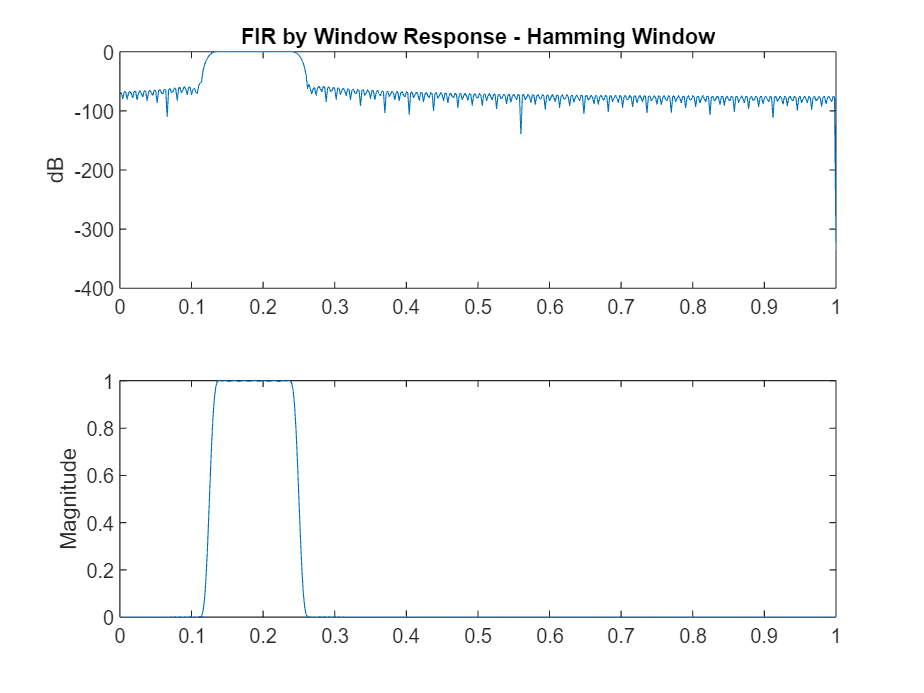

M = 400; %this is the first testing M value we used
M = 296; % this lower value meets the spec and was adjusted based off the M above.

wc2 = pi/4; %first cuttoff value
wc1 = pi/8; %second cutoff value.
%the difference between these is delta w, which is range of the filter.

df = 0.02*pi;

%now, with the values above we can build the ideal low pass as our base
hd = ideal_lp(wc2,M) - ideal_lp(wc1, M);
hm = hamming(M)';%and the hamming window for the filtering we desire based on the signal length
h = hd .* hm; %this will give us what we want to filter through (multiply both together)

%now, we can push through here and display all the additional items
%required to get an accurate view of the function we just built.
[db,mag,pha,grd,w] = freqz_m(h,[1]);
delta_w = 2*pi/1000; %this is the width from the passband to the stopband in the drop!

figure;
subplot(2,1,1);
plot(w/pi,db);
ylabel('dB');
title('FIR by Window Response - Hamming Window')

subplot(2,1,2);
plot(w/pi, mag);
ylabel('Magnitude')


%now, we need to convert this into the s domain. This is required to obtain
%estimations on attenuation
ws1 = wc1 - (df/2);
ws2 = wc2 + (df/2);
filter_length = M;

%now, to make it easier to read the s domain we are REQUIRED to have
%attenuation stopband for the start and end of the windowed signal as in AS
%and AS2
As = -round(max(db(1:1:ws1/delta_w-1))) % Min Stopband attenuation for first stopband

As = 57

As2 = -round(max(db(ws2/delta_w+1:1:501))) % Min Stopband attenuation for second stopband

As2 = 40

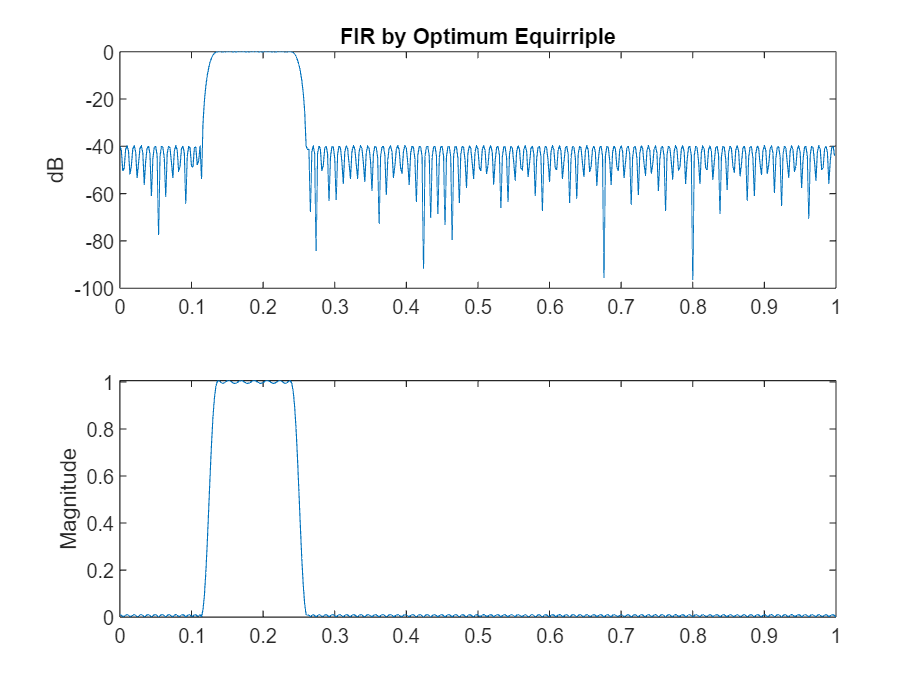

% the attenuation meets the specs

% If we want to use optimum equirripple design, we can use a value of Rp =
% 1 dB
Rp = 0.1; %since this is not given, we are assuming here
As = 40;
%now we can calculate out the passbands for each end
wp1 = wc1 + (df/2);
wp2 = wc2 - (df/2);

%this of this again, and draw it out! the first stop band, first pass band,
%and ending pass and stop band.
f = [ ws1 wp1 wp2 ws2 ] ./ pi; %the frequency range
a = [0 1 0]; %and where the ranges are (low high low in this case)

%now, to display the denominator of the function because since this is FIR
%the bottom will always be 1!
d1 = (1-db2mag(-Rp))/(1+db2mag(-Rp));
d2 = db2mag(-As)*(1+d1);
d = [d2 d1 d2];

[M, fo, ao, W] = firpmord(f,a,d);
h = firpm(M, fo, ao, W);
[db, mag, pha, grd, w] = freqz_m(h,[1]);%as you can see here the value of the denominator is 1!

figure;
subplot(2,1,1);
plot(w/pi,db);
ylabel('dB');
title('FIR by Optimum Equirriple')

subplot(2,1,2);
plot(w/pi, mag);
ylabel('Magnitude')

filter_length = M

filter_length = 211

As = -round(max(db(1:1:ws1/delta_w-1))) % Min Stopband attenuation for first stopband

As = 40

As2 = -round(max(db(ws2/delta_w+1:1:501))) % Min Stopband attenuation for second stopband

As2 = 40

### IIR Filter Designing

clear;
wc = 0.7*pi;
df = 0.1*pi;

%once again, setting up the s domain pieces we require
ws = wc - (df/2);
wp = wc + (df/2);

As = 50;
As = 60; % to meet the 50 dB attenuation above
Rp = 1;

% Analog Prototype Specifications
% we also have to display the omegaS and omegaP here as these are in
% another domain...reliant on the s domain.
T = 1; Fs = 1/T;
OmegaS = wp/T; % we switch the design parameters as butterworth is lowpass
OmegaP = ws/T;

% Analog Butterworth Prototype Filter Calculation:
[cs,ds] = afd_butt(OmegaP,OmegaS,Rp,As);


*** Butterworth Filter Order = 53 


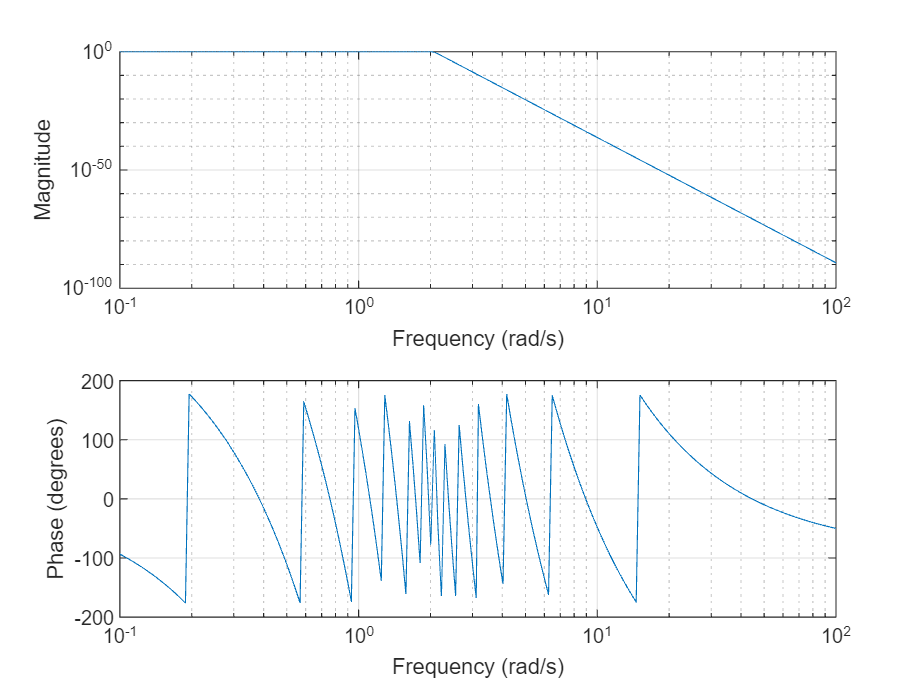

freqs(cs,ds)

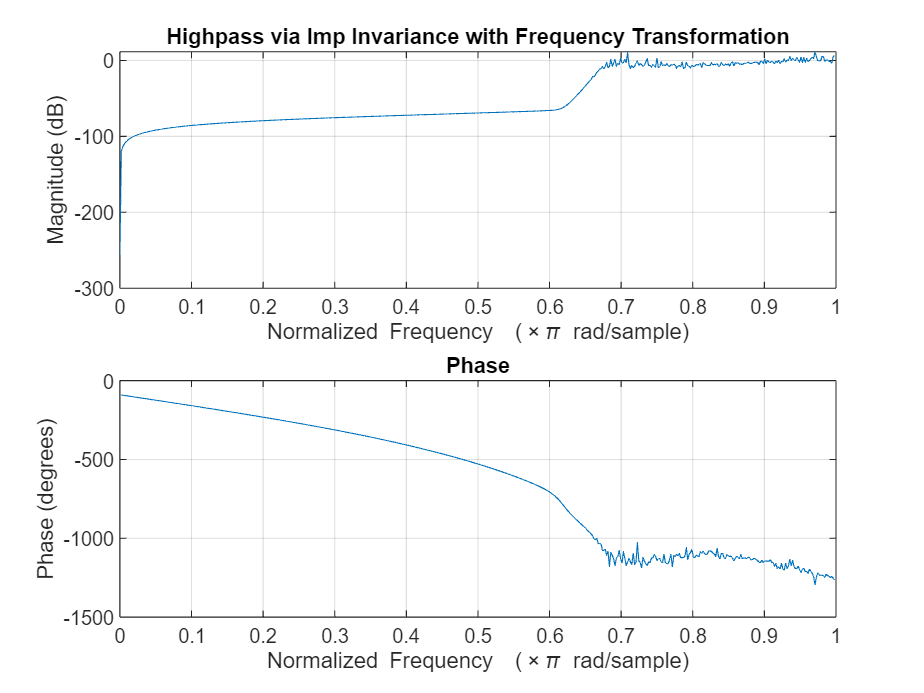


% Impulse Invariance transformation:
[bl,al] = bilinear(cs,ds,Fs);

% We need to find the highpass mapping
% from slide presentation 21, slide 11
wphp = 0.7*pi;
a = -cos((wp + wphp)/2)/cos((wp - wphp)/2);
Nz = -[a 1];
Dz = [1 a];

%zmapping function is used to display based on the slideset 21 slide 11
%tables!
[bh,ah] = zmapping(bl,al,Nz,Dz);
figure;
freqz(bh,ah);
title('Highpass via Imp Invariance with Frequency Transformation')

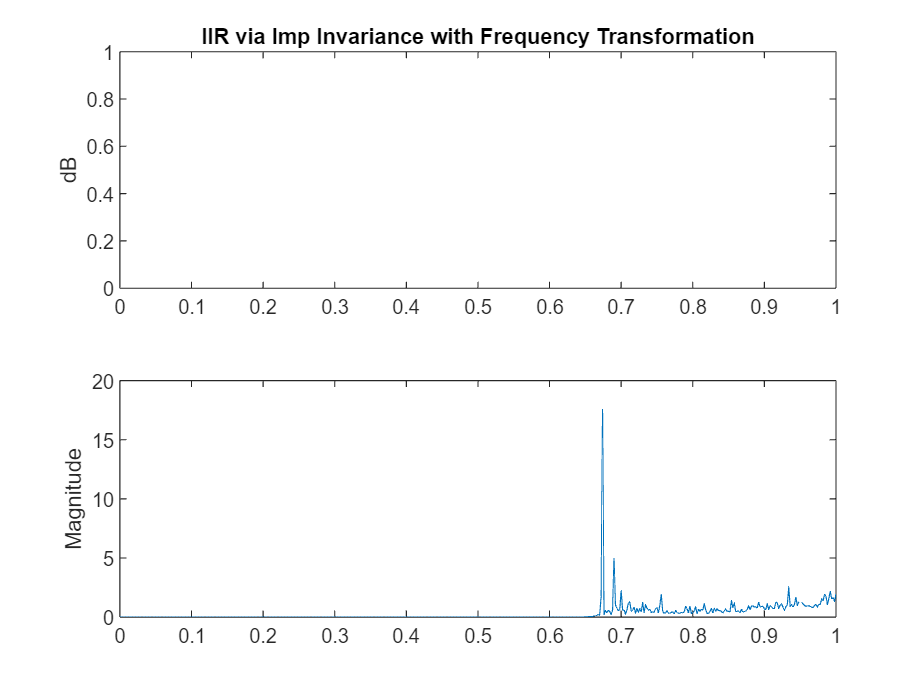

%now that the zmapping has given us the a and b values, we can do freqz_m
%to give us the rest of the ieces we need.
[db, mag, pha, grd, w] = freqz_m(bh,ah);
figure;
subplot(2,1,1);
plot(w/pi,db);
ylabel('dB');
title('IIR via Imp Invariance with Frequency Transformation')
subplot(2,1,2);
plot(w/pi, mag);
ylabel('Magnitude')

wsh = wphp;
delta_w = 2*pi/1000;
filter_order = length(ah)

filter_order = 54

As = -round(max(db(1:1:wsh/delta_w-1))) % Min Stopband attenuation for first stopband

As = Inf

## Helpful Links

[https://www.mathworks.com/help/signal/ug/fir-filter-design.html](https://www.mathworks.com/help/signal/ug/fir-filter-design.html)

## Helpful Functions

function [db,mag,pha,grd,w] = freqz_m(b,a); 
% Modified version of freqz subroutine 
% ------------------------------------ 
% [db,mag,pha,grd,w] = freqz_m(b,a); 
% db = Relative magnitude in dB computed over 0 to pi radians 
% mag = absolute magnitude computed over 0 to pi radians 
% pha = Phase response in radians over 0 to pi radians 
% grd = Group delay over 0 to pi radians 
% w = 501 frequency samples between 0 to pi radians 
% b = numerator polynomial of H(z) (for FIR: b=h) 
% a = denominator polynomial of H(z) (for FIR: a=[1]) 
%
[H,w] = freqz(b,a,1000,'whole'); 
H = (H(1:1:501))'; w = (w(1:1:501))';
mag = abs(H); 
db = 20*log10((mag)/max(mag)); 
pha = angle(H); 
grd = grpdelay(b,a,w); 
end

function hd = ideal_lp(wc, M); 
% Ideal LowPass filter computation 
% -------------------------------- 
% [hd] = ideal_lp(wc,M) 
% hd = ideal impulse response between 0 to M-1 
% wc = cutoff frequency in radians 
% M = length of the ideal filter
%
L = (M-1)/2; n = [0:1:(M-1)]; 
m = n - L; fc2 = wc/pi; hd = fc2*sinc(fc2*m); 
end

function [b,a] = afd_butt(Wp,Ws,Rp,As);
% Analog Lowpass Filter Design: Butterworth
% -----------------------------------------
% [b,a] = afd_butt(Wp,Ws,Rp,As);
% b = Numerator coefficients of Ha(s)
% a = Denominator coefficients of Ha(s)
% Wp = Passband edge frequency in rad/sec; Wp > 0
% Ws = Stopband edge frequency in rad/sec; Ws > Wp > 0
% Rp = Passband ripple in +dB; (Rp > 0)
% As = Stopband attenuation in +dB; (As > 0)
%
if Wp <= 0
error('Passband edge must be larger than 0')
end
if Ws <= Wp
error('Stopband edge must be larger than Passband edge')
end
if (Rp <= 0) | (As < 0)
error('PB ripple and/or SB attenuation ust be larger than 0')
end
N = ceil((log10((10^(Rp/10)-1)/(10^(As/10)-1)))/(2*log10(Wp/Ws)));
fprintf('\n*** Butterworth Filter Order = %2.0f \n',N)
OmegaC = Wp/((10^(Rp/10)-1)^(1/(2*N)));
[b,a]=u_buttap(N,OmegaC);
end


## Helpful Screenshots/Tables